# **Code "Waveform"**

clear
Type = "DCMS1N";
Materiau = "3135";
Eprouvette ='0';
Numero = '1';
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_brute = acces_donnees_brutes();
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
addpath(strcat(repertoire_brute,'/',Type,'/',Materiau,'/',Eprouvette,'.',Numero,'/','EA','/','waveforms'));
nomWF = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);  %Penser à ajouter strcat(Naming,'_','HDD.TXT') pour charger TDD/HDD/waveforms

## Choix waveform

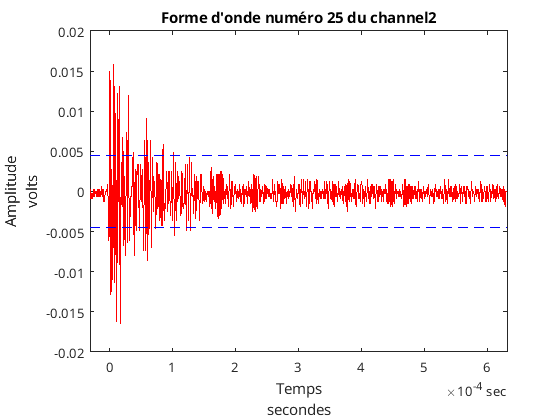

channel = '2';
numero ='25';
Affiseuil = true;
thrdB =33;
detecTime = true;
if detecTime == 0
    Fe = 2*1e6; % Au final Fe est en Hz
    trig = 10*1e-6; % Au final trig est en s
end
%Le 'Current Folder' doit etre le dossier 'waveforms' de l'essai intéréssé
if channel=='Streaming'
    donnees = readtable(strcat(nomWF,'.txt'));
end

if detecTime==0
    datas = readlines(strcat(nomWF,'_',channel,'_',numero,'.txt'));
%     donnees = table(str2double(datas(13:end-1)));
    Temps = linspace(-trig,(height(datas(13:end))-1)/Fe-trig,height(datas(13:end)))';
    donnees = timetable(seconds(Temps),str2double(datas(13:end)));
%     donnees = addvars(donnees,Temps,'Before','Var1');
%     donnees.Properties.VariableNames{'Var1'} = 'Amplitude';
%     donnees.Properties.VariableUnits = {'s' 'V'};
    donnees.Properties.VariableNames = {'Amplitude'};
    donnees.Amplitude(end) = 0;
else
    donnees = readtable(strcat(nomWF,'_',channel,'_',numero,'.txt'));
    donnees.Properties.VariableUnits = {'s' 'V'};
    donnees.Properties.VariableNames{'Var1'} = 'Temps';
    donnees.Properties.VariableNames{'Var2'} = 'Amplitude';
    donnees = timetable(seconds(donnees.Temps),donnees.Amplitude);
    donnees.Properties.VariableNames = ["Amplitude"];
end


% Tracé de la FO
FO = true;
if FO==1
    donneesWF = donnees;
    len = length(donnees.Amplitude);
    i = len;
    r = 0;
    while r==0
        r = donnees.Amplitude(i);
        i = i-1;
    end
    donneesWF(i+12:len,:)=[];
    % Tracé
    figure();
    plot(donneesWF.Time,donneesWF.Amplitude,'r-')
    hold on
    if Affiseuil == 1
        thr = zeros(size(donneesWF.Amplitude))+10^((thrdB+40)/20)*1e-6;
        plot(donneesWF.Time,thr,'b--');
        plot(donneesWF.Time,-thr,'b--');
    end
    xlim([donneesWF.Time(1) donneesWF.Time(end)])
    xlabel({'Temps';'secondes'})
    ylabel({'Amplitude';'volts'})
    title(strcat("Forme d'onde numéro ",numero,' du channel ',channel))
end

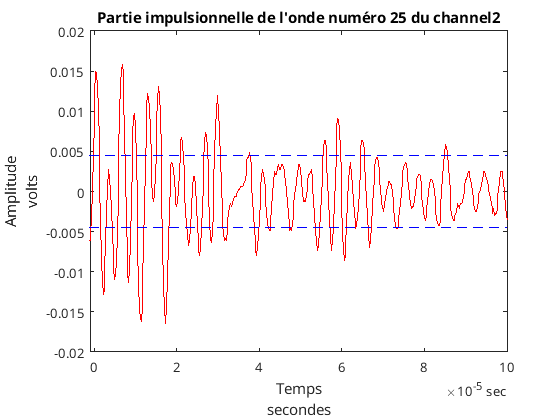

Partieimpulsionnelle = true;
if Partieimpulsionnelle==1
    %xlim([-0.00007 donnees.Time(i+11)])
    figure();
    plot(donnees.Time,donnees.Amplitude,'r-')
    xlabel({'Temps';'secondes'})
    ylabel({'Amplitude';'volts'})
    title(strcat("Partie impulsionnelle de l'onde numéro ",numero,' du channel ',channel))
    xlim([seconds(-0.000001) seconds(0.0001)])
    hold on
    if Affiseuil == 1
        thr = zeros(size(donnees.Amplitude))+10^((thrdB+40)/20)*1e-6;
        plot(donnees.Time,thr,'b--');
        plot(donnees.Time,-thr,'b--');
    end
end

FFT = true;
pspectrum(donnees(200:end));

Subscripting into a table using one subscript (as in t(i)) or three or more subscripts (as in t(i,j,k)) is not supported. Always specify a row subscript and a variable subscript, as in t(rows,vars).

if FFT==1
    len = size(donnees.Time); % Nbre de valeurs discretes de la série étudiée
    L = 1000000*(donnees.Time(len(1))-donnees.Time(1)); % Temps total du signal en µs
    Fs = -1/(1000000*(donnees.Time(1)-donnees.Time(2))); % Freq d'échantillonage en Hz
    Y = fft(donnees.Amplitude); % Calcul FFT
%     Freq = Fs*(0:L/2)/L;
%     plot(Freq,Y);
%    Y = abs(Y/L); % Pour amplitude normalisée ?
    P1 = Y(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1 = 20*log10(P1);
    f = Fs*(0:(L/2))/L;
    figure();
    plot(f,P1) 
    title('Single-Sided Amplitude Spectrum of X(t)')
    xlabel('f (MHz)')
    ylabel('|P1(f)|')
    
    %Tracé du spectre 
    figure();
    Te = 1/Fs;
    N = len(1);
    freq = [0:N-1]/(N*Te);
    tfx = fft(donnees.Amplitude);
    stem(freq/Te,abs(tfx)/N);%stem est un type de plot souvent utilisé pour représenter les spectres
    xlabel('Fréquence en MHz');
    ylabel('Composantes de Fourier (normalisées)');
    xlim([0 Fs/2]);
end
TFR = true;
dt = 60600;
Overlap = 99;
seuil = -100;
freqmax = 1.5;
tempsmax = 300; 

if TFR == 1
    tempsmax = tempsmax*(1e-6);
    Fs = 1/(donnees.Time(2)-donnees.Time(1));
    signal = donnees.Amplitude(1:(Fs*tempsmax));
    SPEC = pspectrum(signal,Fs,"spectrogram","TimeResolution",dt*1e-9,"OverlapPercent",Overlap,"MinThreshold",seuil,"FrequencyLimits",[0,freqmax*1e6]);
    pspectrum(signal,Fs,"spectrogram","TimeResolution",dt*1e-9,"OverlapPercent",Overlap,"MinThreshold",seuil,"FrequencyLimits",[0,freqmax*1e6])
    view(45,65)
    SPEC = 20*log10(SPEC);
    a = SPEC(1:1024,1:1024);
    b = SPEC(1:1024,101:1124);
    c = SPEC(1:1024,31:1054);
    % a = SPEC;
    % b = SPEC;
    % mesh(a)
    % mesh(b)
    shift=POCShift(b,a)
    shift=POCShift(c,a)
    shift=POCShift(b,c)
end

% addpath('/home/tdelaselle/Documents/Codes/Codes persos Matlab/tftb/mfiles');
% signal = donnees.Amplitude;
% temps = donnees.Temps'+3.10000000000000e-05;
% [tfr,t,f] = tfrsp(signal);
% tfrsp(signal);
% % tfrqview(tfr,[],1:3314,'type1');